% % getting whole group workflow (up til now) together

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();

nGroup = 3

% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'



% GROUP MATRIX

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% LOCO NO PUP - makes group matricies, need this for all other figs/analyses

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3



% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 

% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
% LO BEH STATE
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts)

size_loRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts)

size_loRun_stdErrCRF_acrossSess_allPts =      5     7


% HI BEH STATE
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts)

size_hiRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts)

size_hiRun_stdErrCRF_acrossSess_allPts =      5     7


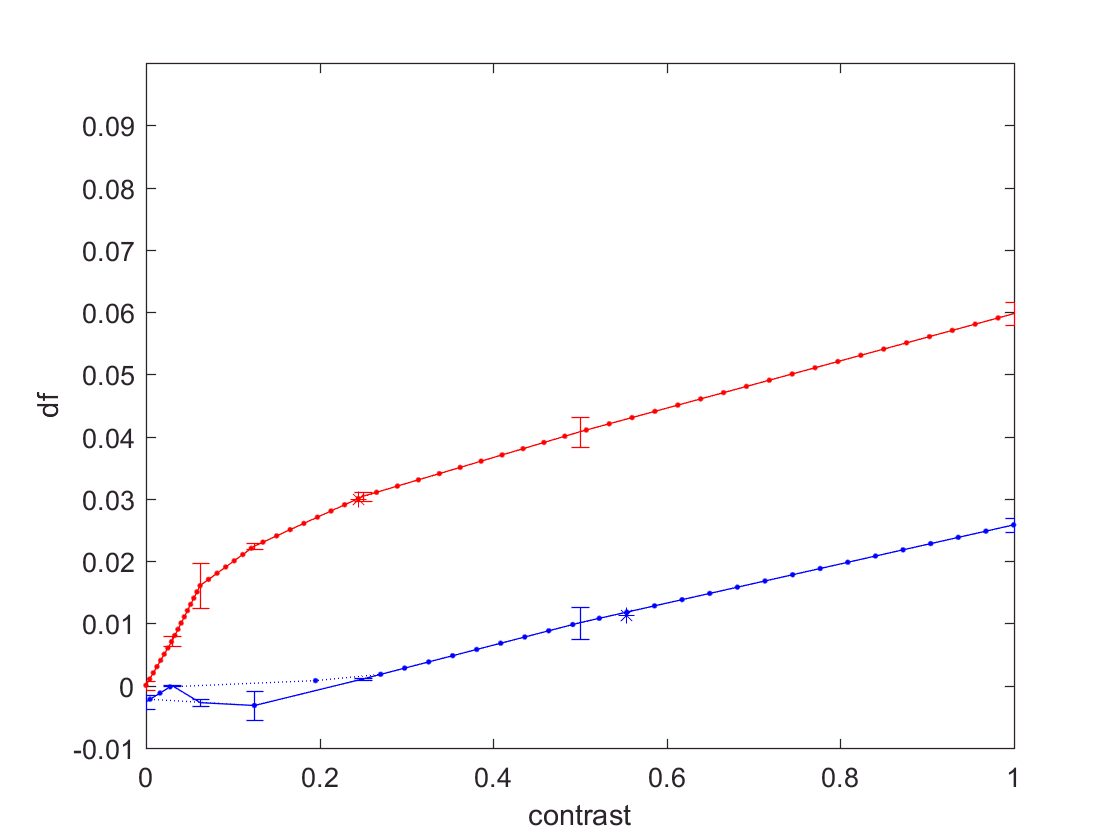


% INTERP - LO beh state

% we now have man CRF across sessions/mice for each visual area

% for 1 dur,
d = 1;
% 1 point, 
i = 1;

% take the ith CRF
ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);
% x is df vector
x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
% resolution of interpolation 
higherRes = 1/1000; 
lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
% the y input to inpterp() is the thing you want interpolated according to the resolution set above
y_is_cons = uniqueContrasts;
% interpolate contrast
lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);

% find con associated 1/2 max df/range value

% find 1/2 max df
% take the range of df (max df - min df)
range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
% divide range by 2
halfOf_range = range/2;
% subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
% find C50 on interpolated curve
% find first higher res df value greater than df_at_C50
idx_df_hiRes_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
% use index to find associated interped cCON value
lo_C50 = lo_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);

% PLOT  - lo only

% figure
% errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'r')
% hold on 
% plot(yi_interpedConsCurve,xi_isDf_higherRes,'b:.')
% hold on 
% plot(lo_C50,lo_df_at_C50,'b*')
% ylim([-0.01 0.1])
% xlim([0 1])


% INTERP - HI beh state

% for 1 dur,
d = 1;
% 1 point, 
i = 1;

% take the ith CRF
ith_mnCRF_acrossSess_AllDurAllPts_hi = hiRun_mnCRF_acrossSess_AllDurAllPts(i,:);
% x is df vector
x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
% resolution of interpolation 
higherRes = 1/1000; 
hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
% the y input to inpterp() is the thing you want interpolated according to the resolution set above
y_is_cons = uniqueContrasts;
% interpolate contrast
hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);

% find con associated 1/2 max df/range value
% find 1/2 max df
% take the range of df (max df - min df)
range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
% divide range by 2
halfOf_range = range/2;
% subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
% find C50 on interpolated curve
% find first higher res df value greater than df_at_C50
idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
% use index to find associated interped cCON value
hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);

% % PLOT hi only
% figure
% errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
% hold on 
% plot(yi_interpedConsCurve,xi_isDf_higherRes,'b:.')
% hold on 
% plot(hi_C50,hi_df_at_C50,'b*')
% ylim([-0.01 0.1])
% xlim([0 1])

% PLOT BOTH beh STATES

figure

errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
hold on 
plot(lo_yi_interpedConsCurve,lo_xi_isDf_higherRes,'b:.')
hold on 
plot(lo_C50,lo_df_at_C50,'b*')

hold on

errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
hold on 
plot(hi_yi_interpedConsCurve,hi_xi_isDf_higherRes,'r:.')
hold on 
plot(hi_C50,hi_df_at_C50,'r*')

ylim([-0.01 0.1])
xlim([0 1])

ylabel('df')
xlabel('contrast')